# Solve Single PDE

Our partial differential equation        $\pi^2 \frac{\partial \;u}{\partial \;t}=\frac{\partial^2 u}{\partial x^2 }\ldotp$       for $0\le x\le 1$ and $t\ge 0$.

Initial conditions: 

                                                         for $t=0$,        we have     $u\left(x,0\right)=\mathrm{sin}\left(\pi x\right)\ldotp$

                                                         at $x=0,\;\;\;\;\;\;\;\;\;$ $u\left(0,t\right)=0,$

                                                         at $x=1$,        $\pi e^{-t} +\frac{\partial u}{\partial x}\left(1,t\right)=0\ldotp$

## Coding Our Equation for pdepe() Solver

Standard form:                              $c\left(x,t,u,\frac{\partial u}{\partial x}\right)\frac{\partial u}{\partial t}=x^{-m} \frac{\partial }{\partial x}\left(x^m f\left(x,t,u,\frac{\partial u}{\partial x}\right)\right)+s\left(x,t,u,\frac{\partial u}{\partial x}\right)$.

Our equation:                                $\pi^2 \frac{\partial u}{\partial t}=x^0 \frac{\partial }{\partial x}\left(x^0 \frac{\partial u}{\partial x}\right)+0$.

Therefore:                                     $c\left(x,t,u,\frac{\partial u}{\partial x}\right)=\pi^2$,        $m=0$,      $f\left(x,t,u,\frac{\partial u}{\partial x}\right)=\frac{\partial u}{\partial x}$,          $s\left(x,t,u,\frac{\partial u}{\partial x}\right)=0$

Writing a function:                         `[c,f,s] = pdex1pde(x,t,u,dudx)`:

- `x` - spatial variable,     t - time variable,    u(x,t) - DEPENDENT variable,    dudx -  $\partial u/\partial x$, 

- [c, f, s] - expected by pdepe(), coded in terms of variables x, t, u and dudx

As a result, the equation in this example can be represented by the function:

## Code Initial Condition

The initial condition of u0 is applied at the first time value `tspan(1) for all x: u0 = pdex1ic(x)`.

The corresponding function is 

## Code Boundary Conditions

For problems posed on the interval $a\le x\le b$, the boundary conditions apply for all $t$ and either $x=a$ or $x=b$. The standard form for the boundary conditions expected by the solver is


$$p\left(x,t,u\right)+q\left(x,t\right)f\left(x,t,u,\frac{\partial u}{\partial x}\right)=0\ldotp$$


Rewrite the boundary conditions in this standard form and read off the coefficient values.

For $x=0$, the equation is 


$$u\left(0,t\right)=0\;\to \;u+0\cdot \frac{\partial u}{\partial x}=0\ldotp$$
 

The coefficients are:

- 
$$p\left(0,t,u\right)=u$$


- 
$$q\left(0,t\right)=0$$


For $x=1$, the equation is 


$$\pi e^{-t} +\frac{\partial u}{\partial x}\left(1,t\right)=0\;\to \pi e^{-t} +1\cdot \frac{\partial u}{\partial x}\left(1,t\right)=0\ldotp$$


The coefficients are:

- 
$$p\left(1,t,u\right)=\pi e^{-t}$$


- 
$$q\left(1,t\right)=1$$


You need only specify the values of $p\left(x,t,u\right)$ and $q\left(x,t\right)$ at each boundary.

The boundary function should use the function signature `[pl,ql,pr,qr] = pdex1bc(xl,ul,xr,ur,t)`:

- The inputs `xl` and `ul` correspond to $u$ and $x$ for the left boundary.

- The inputs `xr` and `ur` correspond to $u$ and $x$ for the right boundary.

- `t` is the independent time variable.

- The outputs `pl` and `ql` correspond to $p\left(x,t,u\right)$ and $q\left(x,t\right)$ for the left boundary ($x=0$ for this problem).

- The outputs `pr` and `qr` correspond to $p\left(x,t,u\right)$ and $q\left(x,t\right)$ for the right boundary ($x=1$ for this problem).

 The boundary conditions in this example are represented by the function:

## Select Solution Mesh

Specify the mesh points $\left(t,x\right)$ for `pdepe()`.

20 equally spaced points of x in the spatial interval [0,1] and five values of `t` from the time interval [0,2].

x = linspace(0,1,20);
t = linspace(0,2,5);

## Solve Equation

Using the symmetry `m`, the PDE equation, the initial conditions, the boundary conditions, and the meshes for `x` and `t`. 

m = 0;
sol = pdepe( m, @pdex1pde, @pdex1ic, @pdex1bc, x, t);

`pdepe()` returns the solution in a 3-D array `sol`, where `sol(i,j,k)` approximates the `k-`th component of the solution $u_k$ evaluated at `t(i)` and `x(j)`.

The size of `sol` is `length(t)`-BY-`length(x)`-by-`length(u0)`, since `u0` specifies an initial condition for each solution component.

Extract the first solution component from `sol`.

u = sol(:,:,1);

For this problem, we have only one component, so `sol` is a 5-by-20 matrix, but in general you can extract the `k-`th solution component with the command `u = sol(:,:,k)`.

## Plot Solution

Create a surface plot of the solution.

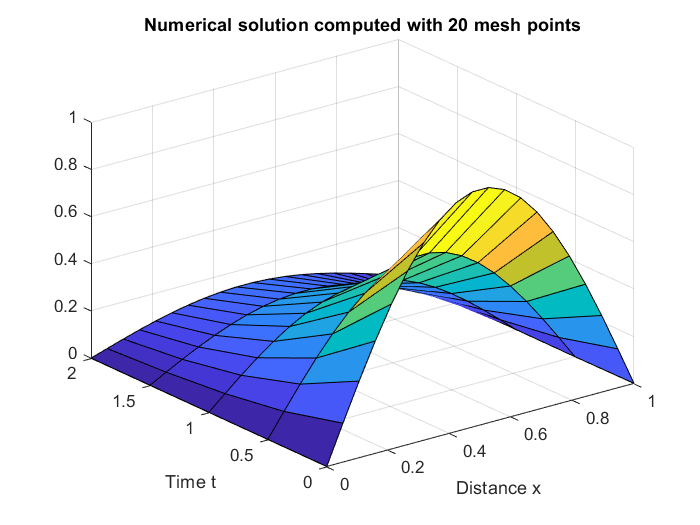

surf(x,t,u)
title('Numerical solution computed with 20 mesh points')
xlabel('Distance x')
ylabel('Time t')

For our initial condition and boundary conditions, an analytical solution exists:


$$u\left(x,t\right)=e^{-t} \;\;\sin \left(\pi x\right)\ldotp$$


Ploting the analytical solution - using the same mesh points.

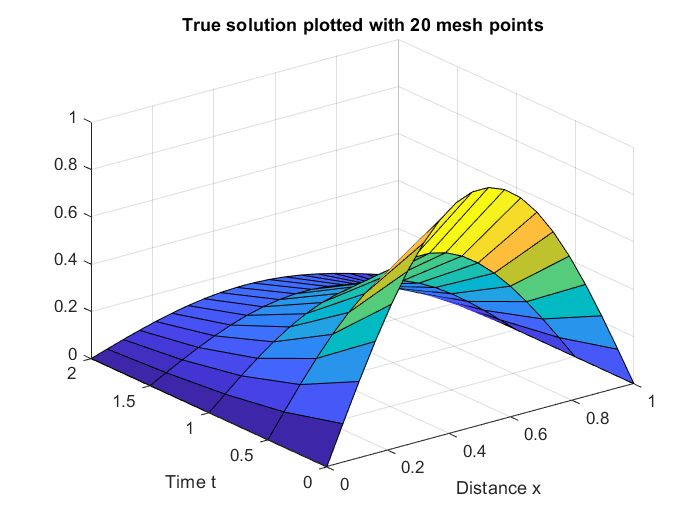

surf(x,t,exp(-t)'*sin(pi*x))
title('True solution plotted with 20 mesh points')
xlabel('Distance x')
ylabel('Time t')

Comparing the numerical and analytical solutions at $t_f$, the final value of $t$. In this example $t_f =2$.

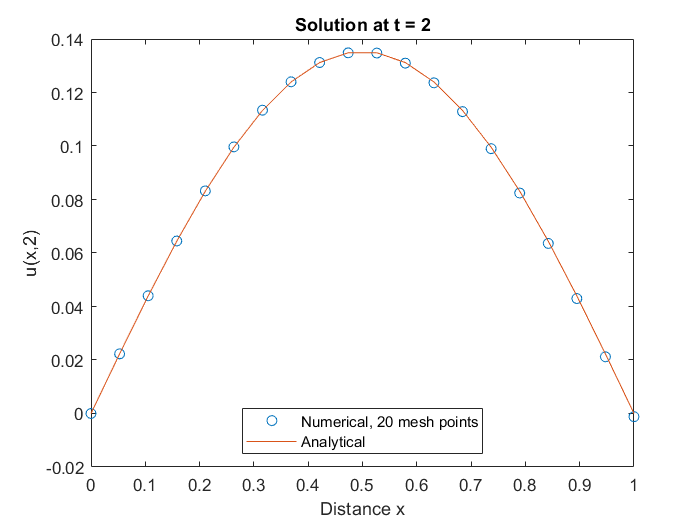

plot(x,u(end,:),'o',x,exp(-t(end))*sin(pi*x))
title('Solution at t = 2')
legend('Numerical, 20 mesh points','Analytical','Location','South')
xlabel('Distance x')
ylabel('u(x,2)')

## Local Functions

function [c,f,s] = pdex1pde(x,t,u,dudx) % Equation to solve
c = pi^2;
f = dudx;
s = 0;
end
%----------------------------------------------
function u0 = pdex1ic(x) % Initial conditions
u0 = sin(pi*x);
end
%----------------------------------------------
function [pl,ql,pr,qr] = pdex1bc(xl,ul,xr,ur,t) % Boundary conditions
pl = ul;
ql = 0;
pr = pi * exp(-t);
qr = 1;
end
%----------------------------------------------

*Copyright 2019 The MathWorks, Inc.*